# CTD-DO Calibration Example using data from AR69-01

This worked example was prepared by Kristen Fogaren (fogaren@bc.edu) to include with *Oxygen optodes on oceanographic moorings: recommendations for deployment and in-situ calibration* by Una Kim Miller, Kristen E. Fogaren, Dariia Atamanchuk, Jannes Koelling, Clare Johnson, Isabela Le Bras, Margaret Lindeman, Hiroki Nagao, David P. Nicholson, Hilary Palevsky, Ellen Park, Meg Yoder, Jaime Palter (doi: ***). 

The following worked example is provided to demonstrate the workflow for calibrating CTD-DO sensors using Winkler samples from data collected on AR69-01. Since SBE does not currently provide processing pipelines for calibration of SBE 43 oxygen sensors, this code is intended to be a starting point for users who are interested in calibrating SBE 43 oxygen sensors using the suggested Seabird oxygen calibration equation. It is specific to our group's file formats, but can be applied to different file formats with alterations of the code. 

## Set up workspace and assemble bottle/profile files and SBE43 calibration coefficients 

#### **1. Add required Matlab toolboxes to workspace **

- [*Seabird Toolbox*](https://github.com/rejectedbanana/Sea-Bird-Toolbox) and [*Seabird Oxygen Toolbox*](https://github.com/rejectedbanana/Sea-Bird_Oxygen_Toolbox) developed by KiM MARTiNi

- [*GSW Toolbox*](https://github.com/TEOS-10/GSW-Matlab) (see [https://www.teos-10.org/software.htm](https://www.teos-10.org/software.htm) for more information).  

#### 2. CTD-DO Bottle Files

- Raw CTD data have been converted from .hex files to .cnv files using the *Seabird Data Processing* software and "DATCNV" module 

- *SBE Data Processing* software is available to download as Seasoft V2 [here](https://software.seabird.com/?_gl=1%2Ac06zv7%2A_ga%2AMTg5NTA1MDI2NC4xNzE2MzAzNDgw%2A_ga_RV3R2EEC7Q%2AMTcxNjMwMzQ3OS4xLjAuMTcxNjMwMzQ3OS4wLjAuMA..)

- See *Seabird Data Processing* notes (from Seabird documentation) for more information 

- File output variables must include a minimum of pressure, temperature, conductivity, and dissolved oxygen (V), lat, lon 

- Recommend that oxygen is processed without the tau correction

- Recommend that oxygen is processed with the default hysteresis correction 

- Bottle summary files with an extention of *.btl are created using the "BOTTLESUM" module in *Seabird Data Processing* software

- *.btl files are then converted to *.csv files for reading into Matlab workspace using Btl_to_csv.ipynb 

- See ar69-01_007.btl as example of CTD-DO Bottle File  

#### 3. Winkler Summary File for Cruise 

- File that includes oxygen concentrations determined using shipboard Winkler titrations for discrete water samples

- Winkler replicates are treated as individual points and not averaged by Cast/Bottle number 

- Variables must include mimimum of Cast number, bottle number and Winkler value 

- See 'Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx' as example of Winkler Summary File 

#### 4. Salinity-calibrated Bottle Files and cast files 

- File that includes salinity values that have been calibrated using discrete water samples measured shipboard for salts 

- Whenever possible, oxygen sensor calibration should be done using bottle-calibrated salinity measurements 

- Varibles must include miminum of Cast number, bottle number and finalized salinity value 

- See AR69-01_007.cbot_s as example of salinity-calibrated bottle file

- See 'AR69-01_006.dcc' as example of salinity-calibrated profile  

- Format for this file varies depending on group/individual who calibrated the conductivity sensor(s) 

- Cast data was binned into 2 dbar bins and split into upcast and downcast 

#### 5. SBE-43 Dissolved oxygen sensor coefficients 

- Sea-bird factory calibration coefficients for the SBE43 

- One way to find these coefficients is in *Seabird Data Processing* software: Run data conversion module --> modify instrument config file from cruise --> double click on sensor of interest (ex. Oxygen SBE 43)

- See 'SBE43_SN1960.xml' as example of factory calibration coefficients 

**6. Uncalibrated CTD-DO Casts **

- CTD-DO cast files that have been converted from .hex files to .cnv files using the *Seabird Data Processing* software

- File output variables must include a minimum of pressure, temperature, conductivity, and dissolved oxygen (V), lat, lon

- Recommend that oxygen is processed without the tau correction

- Recommend that oxygen is processed with the default hysteresis correction 

- See header of *.cnv files for casts for details regarding SBE modules used to process CTD-DO casts

- Oxygen voltages were processed without the tau correction and with the default hysteresis correction

- Oxygen voltages were corrected for a sensor time lag of 6 seconds

- Data was binned into 2 dbar bins and split into upcast and downcast (matches Salinity-calibrated files)

- See 'dar69-01_006.cnv' as an example of uncalibrated CTD-DO Cast processed using *Seabird Data Processing* software

### Add required Matlab toolboxes for processing

% Specific to KEF computer
addpath('G:\My Drive\Matlab_work\Github\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\Github\Sea-Bird-Toolbox')
addpath(genpath('G:\My Drive\Matlab_work\Github\GSW-Matlab'))
% Location of files
addpath('G:\My Drive\Matlab_work\BC\Fogaren-OOI-Irminger\CTD_Processing') 

### Read in processed bottle files and Winkler data to workspace

% Directories where bottle files are stored, specific to KEF computer  
DO_dir = 'C:\Users\fogaren\Documents\Python\Bottle_Files\Year9'; 
sal_dir = 'G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9\From_Leah'; 
Wink_dir = 'G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9'; 

% Read in Winkler Summary File  
cd(Wink_dir)
% Winkler file name 
Winkler_file = 'Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx'; 

Winklers = readtable(Winkler_file,'TextType','string');
% Number of Winklers depends on replicates made 
Winklers.Winkler1_mLL = double(Winklers.Winkler1_mLL);
Winklers.Winkler2_mLL = double(Winklers.Winkler2_mLL);
Winklers.Winkler3_mLL = double(Winklers.Winkler3_mLL);

% Read in salinity-calibrated bottle files 
cd(sal_dir)
salbtlfiles = ls('*.cbot_s'); % List of sal calibrated bottle file
% Pulls out cast numbers that have bottle files 
% location of cast number in string depends on file name convention 
salbtlcasts = str2double(string(salbtlfiles(:,9:11))); 

% Read in CTD-DO bottle summary files 
cd(DO_dir)
DObtlfiles = ls('*.csv'); % List of DO processed bottle files 
% Pulls out cast numbers that have bottle files 
DObtlcasts = str2double(string(DObtlfiles(:,9:11))); 

% Make sure that there is a salinity bottle file for each of the DO files 
if DObtlcasts == salbtlcasts 
    addpath(sal_dir)
    addpath(DO_dir)    
else
    disp('Caution: Issue with Btl Cast Numbers!')
end

### Calibration information from SBE xmlcon file 

% Same Oxygen Sensor for whole cruise 
cal.SOC = double(4.46780e-001);
cal.VOFFSET = double(-5.08600e-001);
cal.A = double(-5.00190e-003);
cal.B = double(2.51320e-004);
cal.C = double(-3.59380e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.22000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1960';
cal.OCALDATE = '31-Jul-21';

H = [-0.033, 5000, 1450]; % Default

### Combine bottle files

- `combine_btl_files` function at the end of this file reads in salinity calibrated bottle files, DO bottle files with default hysteresis corrected oxygen voltages, and Winkler summary file and combines them by Cast/Bottle number

- `combine_btl_files` function also calculates different hydrographic variables and converts Winkler concentrations from ml/l to umol/kg using the Gibbs Seawater Toolbox and bottle-calibrated salinity data 

- This function is specific to how the different input files are formatted; can be modified for different formatting 

- Bottle files are indexed by cast number in **btlsum** variable (e.g, btlsum{1} == bottle files for cast 1)

- **btlsum_tbl **is table that includes all casts 

- User must input which CTD package to process oxygen data with. Most rosettes are equipped with two packages. We recommend use of CTD temp/salinity data for the CTD package inline with the DO sensor unless that data is unusable

% Set CTD sensor to the package that is inline with oxygen sensor unless
% something wrong with data 
CTD_sen = 1; % Use primary or secondary CTD temp and sal

btlsum = []; % Indexes by cast number btlsum{5} == cast 5; 
% Combine files and calculate sea water properties for CTD sensor number 
for i = 1:height(salbtlcasts) % Number of bottle summary files 
    btlsum{salbtlcasts(i)} = combine_btl_files(salbtlfiles(i,:),DObtlfiles(i,:),...
        Winklers(Winklers.Cast == salbtlcasts(i),:),CTD_sen) ;
end

% Pull all bottle files and create one large table 
btlsum_tbl = [];
for i = 1:length(btlsum)
    btlsum_tbl = [btlsum_tbl; btlsum{i}];
end
btl_num = unique(btlsum_tbl.Cast);

### Non linear multiple regression (NLMR) using SBE functional form 

- Uses Seabird oxygen calibration equation 

- Oxygen solubility calculated using GSW Toolbox

- Treats replicate Winklers as individual inputs to model  

- Up to the end user to determine if want to use a constant SOC term (SOCk) or a SOC term that changes as a function of cruise time (SOCdt) or cast number (SOCcn), and if SOC term is going to be applied to groups throughout the cruise 

- This example found that the example cruise data should be treated as one group

- Applies a SOCk for the whole cruise, examines residuals as function of cruise time/cast number, and determines that a SOC term that varies as a function of cast number minimized the residuals (Winklers - CTDDO values)

#### NMLR with constant SOC term (SOCk) with all casts as one group 

% Set up inputs; number of columns for X depends on number of Winkler replicates; 
X = [[btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts],...
    [btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg],...
    [btlsum_tbl.t; btlsum_tbl.t; btlsum_tbl.t],...
    [btlsum_tbl.prs; btlsum_tbl.prs; btlsum_tbl.prs]];

% For looking at which Winklers were flagged as outliers 
bad_casts = [btlsum_tbl.Cast; btlsum_tbl.Cast; btlsum_tbl.Cast];
btl_check = [btlsum_tbl.Bottle; btlsum_tbl.Bottle; btlsum_tbl.Bottle];

Winklers_to_use = [btlsum_tbl.Winkler1_umolkg; ...
    btlsum_tbl.Winkler2_umolkg; btlsum_tbl.Winkler3_umolkg];
pdens = [btlsum_tbl.prho; btlsum_tbl.prho; btlsum_tbl.prho];

% SBE functional form (SBE provided oxygen calibration equation) 
modelfun = @(b,x)(b(1)*(x(:,1) + cal.VOFFSET)).*x(:,2)...
    .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
    .*exp((b(2)*x(:,4))./(x(:,3) + 273.15));

beta0 = [cal.SOC 0]; % Starting values for coefficient iterations 

%Non linear multiple regression to get b1 (SOC) and b2 (E term) from SBE
%functional form using all Winklers_umolkg (from calibrated T/S data) 
% Run non linear model fit with all Winkler/CTD oxygen 
% (volts with default hysteresis correction applies) values

% Run 1 
mdl1 = fitnlm(X,Winklers_to_use,modelfun,beta0)

mdl1 = Nonlinear regression model:
    y ~ (b1*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    b1     0.45971     0.0021327    215.56    5.5353e-194
    b2    0.038967    0.00088908    43.828     3.0877e-89


Number of observations: 157, Error degrees of freedom: 155
Root Mean Squared Error: 11.2
R-Squared: 0.515,  Adjusted R-Squared 0.512
F-statistic vs. zero model: 5.27e+04, p-value = 2.58e-220

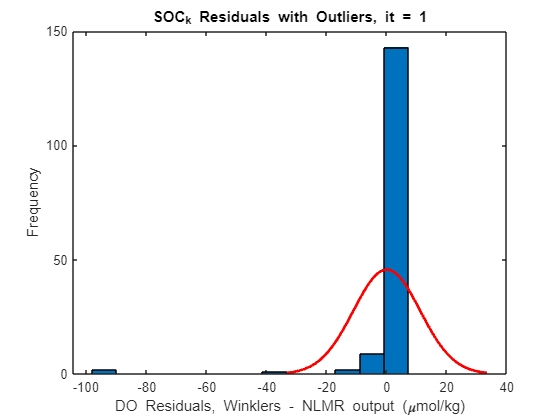

figure
histfit(mdl1.Residuals.raw)
title('SOC_k Residuals with Outliers, it = 1')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 2 
Winkler_outliers1 = find(isoutlier(mdl1.Residuals.Raw,'median') == 1);

% Run 2 
% Exclude outliers from NLMR model run 
mdl2 = fitnlm(X,Winklers_to_use,modelfun,beta0,'Exclude',Winkler_outliers1)

mdl2 = Nonlinear regression model:
    y ~ (b1*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    b1     0.46427    0.00022682    2046.9              0
    b2    0.037948    9.3795e-05    404.58    7.1959e-226


Number of observations: 149, Error degrees of freedom: 147
Root Mean Squared Error: 1.14
R-Squared: 0.99,  Adjusted R-Squared 0.99
F-statistic vs. zero model: 4.84e+06, p-value = 0

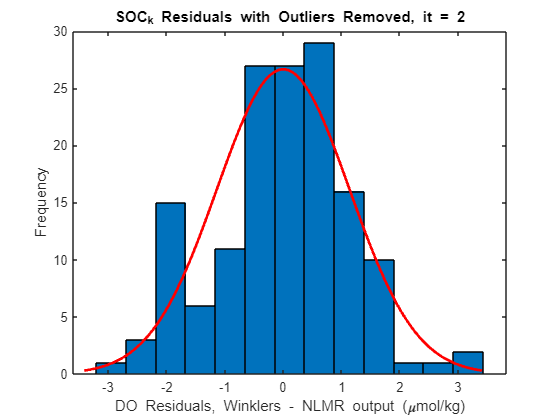

figure
histfit(mdl2.Residuals.Raw)
title('SOC_k Residuals with Outliers Removed, it = 2')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 3 
ind = find(isoutlier(mdl2.Residuals.raw,'median') == 1);
Winkler_outliers2 = [ind; Winkler_outliers1];

% Run 3
% Exclude outliers from NLMR model run 
mdl3 = fitnlm(X,Winklers_to_use,modelfun,beta0,'Exclude',Winkler_outliers2)

mdl3 = Nonlinear regression model:
    y ~ (b1*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    b1     0.46427    0.00021234    2186.4              0
    b2    0.037928    8.7417e-05    433.88    2.6269e-226


Number of observations: 146, Error degrees of freedom: 144
Root Mean Squared Error: 1.06
R-Squared: 0.991,  Adjusted R-Squared 0.991
F-statistic vs. zero model: 5.51e+06, p-value = 0

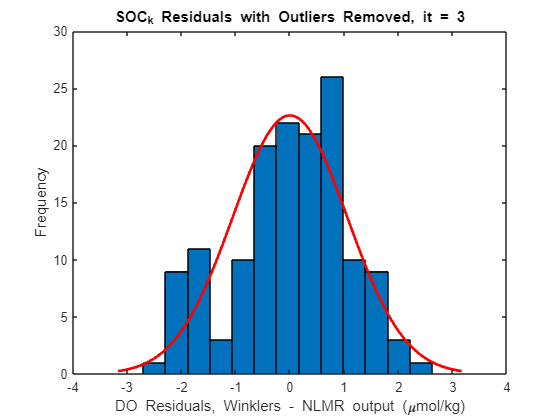

figure
histfit(mdl3.Residuals.Raw)
title('SOC_k Residuals with Outliers Removed, it = 3')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 4 
ind = find(isoutlier(mdl3.Residuals.raw,'median') == 1);
Winkler_outliers3 = [ind; Winkler_outliers2];

% Run 4
% Exclude outliers from NLMR model 
mdl4 = fitnlm(X,Winklers_to_use,modelfun,beta0,'Exclude',Winkler_outliers3)

mdl4 = Nonlinear regression model:
    y ~ (b1*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate        SE        tStat       pValue   
          ________    __________    ______    ___________

    b1     0.46427    0.00021234    2186.4              0
    b2    0.037928    8.7417e-05    433.88    2.6269e-226


Number of observations: 146, Error degrees of freedom: 144
Root Mean Squared Error: 1.06
R-Squared: 0.991,  Adjusted R-Squared 0.991
F-statistic vs. zero model: 5.51e+06, p-value = 0

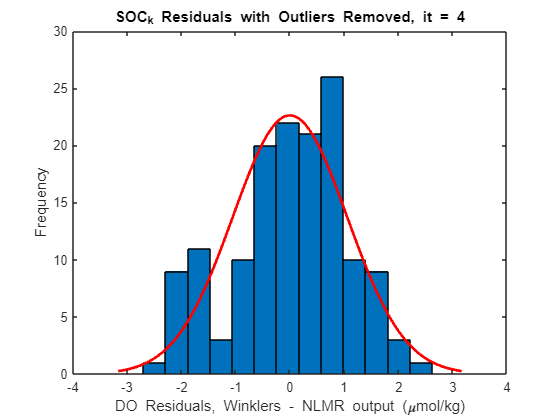

figure
histfit(mdl4.Residuals.Raw)
title('SOC_k Residuals with Outliers Removed, it = 4')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 5 
ind = find(isoutlier(mdl4.Residuals.raw,'median') == 1);
Winkler_outliers4 = [ind; Winkler_outliers3];

% no additional outliers found 

#### Examine residuals for NMLR with constant SOC term (SOCk) with all casts as one group 

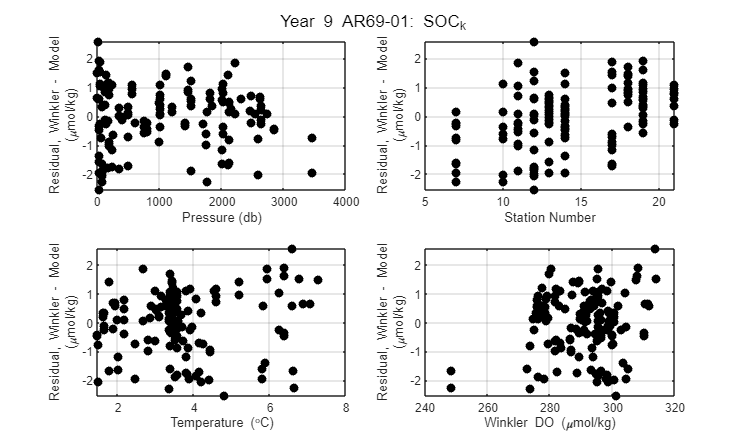

%Plot residuals versus pressure, time, station, DO concentration with outliers removed   
mdlcal_k = mdl4;
cal.SOCcalc = mdlcal_k.Coefficients.Estimate(1);
cal.Ecalc = mdlcal_k.Coefficients.Estimate(2);
cal.gain = cal.SOCcalc/cal.SOC;
cal.Winkler1_outliers = Winkler_outliers4(Winkler_outliers4 < height(btlsum_tbl));
cal.Winkler2_outliers = Winkler_outliers4(Winkler_outliers4 > ...
    height(btlsum_tbl) & Winkler_outliers4 < 2*height(btlsum_tbl)) - height(btlsum_tbl);
cal.Winkler3_outliers = Winkler_outliers4(Winkler_outliers4 ...
    > 2*height(btlsum_tbl) & Winkler_outliers4 < 3*height(btlsum_tbl)) - 2*height(btlsum_tbl);

out_NLMR = sortrows([bad_casts(Winkler_outliers4) btl_check(Winkler_outliers4)...
    Winklers_to_use(Winkler_outliers4)/44.661/1000.*pdens(Winkler_outliers4)],[1 2]);

% plot of residuals 
f = figure;
f.Position = [100 100 840 500];
%Plot residuals versus pressure 
subplot(2,2,1)
plot(btlsum_tbl.prs, mdlcal_k.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20); 
hold on;
plot(btlsum_tbl.prs, mdlcal_k.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.prs, mdlcal_k.Residuals.raw((height(btlsum_tbl)*2+1):end),'.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Pressure (db)')
grid on

%Plot residuals versus cast number/time 
subplot(2,2,2)
plot(btlsum_tbl.Cast, mdlcal_k.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20);
hold on;
plot(btlsum_tbl.Cast, mdlcal_k.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.Cast, mdlcal_k.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Station Number')
grid on

%Plot residuals versus temperature 
subplot(2,2,3)
plot(btlsum_tbl.t, mdlcal_k.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20); 
hold on;
plot(btlsum_tbl.t, mdlcal_k.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.t, mdlcal_k.Residuals.raw((height(btlsum_tbl)*2+1):end),'.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Temperature (\circC)')
grid on

%Plot residuals versus oxygen concentration 
subplot(2,2,4)
plot(btlsum_tbl.Winkler1_umolkg, mdlcal_k.Residuals.raw(1:height(btlsum_tbl)),...
    '.k','Markersize',20); 
hold on;
plot(btlsum_tbl.Winkler2_umolkg, mdlcal_k.Residuals.raw(height(btlsum_tbl)...
    +1:(height(btlsum_tbl)*2)),'.k','Markersize',20)
plot(btlsum_tbl.Winkler3_umolkg, mdlcal_k.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Winkler DO (\mumol/kg)')
grid on
sgtitle('Year 9 AR69-01: SOC_k')

### Look at drift of SOC in time and by cast number

- Using the E term calculated above and the SBE functional form, calculate the SOC term for each Winkler

- Group SOC terms by cast number and plot versus cast number or cruise time to examine potential drift

- Determined that SOC term does drift over the cruise

- Next use NLMR to determine an SOC term that varies over the course of the cruise. 

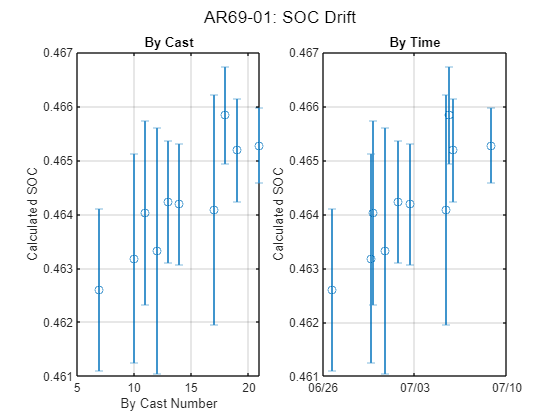

% New E term calculated above (cal.Ecalc)
Tempcorr = 1 + cal.A*btlsum_tbl.t + cal.B*btlsum_tbl.t.^2 + cal.C*btlsum_tbl.t.^3;
Prescorr = exp(cal.Ecalc*btlsum_tbl.prs./(btlsum_tbl.t + 273.15));

% Group SOC calculations by cast number 
cn = unique(btlsum_tbl.Cast(~isnan(btlsum_tbl.Winkler1_umolkg)));

% Remove outliers from Winklers 
Winkler1_umolkg_wout_outliers = btlsum_tbl.Winkler1_umolkg; 
Winkler2_umolkg_wout_outliers = btlsum_tbl.Winkler2_umolkg; 
Winkler3_umolkg_wout_outliers = btlsum_tbl.Winkler3_umolkg;
Winkler1_umolkg_wout_outliers(cal.Winkler1_outliers) = NaN;
Winkler2_umolkg_wout_outliers(cal.Winkler2_outliers) = NaN;
Winkler3_umolkg_wout_outliers(cal.Winkler3_outliers) = NaN;

% Preallocate arrays 
driftdt = []; %NaN(1,length(cn));
SOCdt = []; %NaN(1,length(cn));
SOCstd = []; %NaN(1,length(cn));

% Calculate SOC for each Winkler sample with same E term (cal.Ecalc) 
SOCcalc1 = Winkler1_umolkg_wout_outliers...
    ./(Tempcorr.*Prescorr.*btlsum_tbl.O2sol_umolkg.*(btlsum_tbl.oxy_volts+cal.VOFFSET));
SOCcalc2 = Winkler2_umolkg_wout_outliers...
    ./(Tempcorr.*Prescorr.*btlsum_tbl.O2sol_umolkg.*(btlsum_tbl.oxy_volts+cal.VOFFSET));
SOCcalc3 = Winkler3_umolkg_wout_outliers...
    ./(Tempcorr.*Prescorr.*btlsum_tbl.O2sol_umolkg.*(btlsum_tbl.oxy_volts+cal.VOFFSET));
SOCcalc = [SOCcalc1; SOCcalc2; SOCcalc3];
Castx3 = [btlsum_tbl.Cast; btlsum_tbl.Cast; btlsum_tbl.Cast];
Datex3 = [btlsum_tbl.Date; btlsum_tbl.Date; btlsum_tbl.Date];

% calculate mean time, mean SOC, and std of SOC grouping by cast number  
for i = 1:length(cn)
    driftdt(i) = mean(datenum(Datex3(Castx3 == cn(i))),'omitnan');
    SOCdt(i) = mean(SOCcalc(Castx3 == cn(i)),'omitnan');
    SOCstd(i) = std(SOCcalc(Castx3 == cn(i)),'omitnan');
end

% Plot SOC mean (+-std) for each cast as function of cruise cast number or
% cruise time 
figure
subplot(1,2,1)
errorbar(cn,SOCdt,SOCstd,'o')
ylabel('Calculated SOC')
grid on
xlabel('By Cast Number')
title('By Cast')
sgtitle('AR69-01: SOC Drift')
SOCcnR = min(min(corrcoef([cn SOCdt'],'Rows','complete')));

subplot(1,2,2)
errorbar(driftdt,SOCdt,SOCstd,'o')
ylabel('Calculated SOC')
datetick
grid on
title('By Time')

SOCdtR = min(min(corrcoef([driftdt' SOCdt'],'Rows','complete')));

## NMLR with SOC term that varies with cruise time

% Determine cruise time 
dt = datenum(btlsum_tbl.Date) - datenum(btlsum_tbl.Date(1)); % minus first cast time

X_dt = [[btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts],...
    [btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg],...
    [btlsum_tbl.t; btlsum_tbl.t; btlsum_tbl.t],...
    [btlsum_tbl.prs; btlsum_tbl.prs; btlsum_tbl.prs],...
    [dt; dt; dt]];

bad_casts = [btlsum_tbl.Cast; btlsum_tbl.Cast; btlsum_tbl.Cast];
btl_check = [btlsum_tbl.Bottle; btlsum_tbl.Bottle; btlsum_tbl.Bottle];
Winklers_to_use = [btlsum_tbl.Winkler1_umolkg; ...
    btlsum_tbl.Winkler2_umolkg; btlsum_tbl.Winkler3_umolkg];
pdens = [btlsum_tbl.prho; btlsum_tbl.prho; btlsum_tbl.prho];

% SBE functional form with SOC as a function of cruise time 
modelfun_dt = @(b,x)((b(3)*x(:,5) + b(1)).*(x(:,1) + cal.VOFFSET)).*x(:,2)...
    .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
    .*exp((b(2)*x(:,4))./(x(:,3) + 273.15));

beta0_dt = [cal.SOC 0 0]; % Starting values for coefficient iterations 

mdl_dt1 = fitnlm(X_dt,Winklers_to_use,modelfun_dt,beta0_dt)

mdl_dt1 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate         SE        tStat       pValue   
          _________    __________    ______    ___________

    b1      0.45281     0.0034345    131.84    2.9164e-160
    b2        0.039    0.00087539    44.552     6.8911e-90
    b3    0.0011199    0.00044262      2.53       0.012409


Number of observations: 157, Error degrees of freedom: 154
Root Mean Squared Error: 11
R-Squared: 0.534,  Adjusted R-Squared 0.528
F-statistic vs. zero model: 3.64e+04, p-value = 2.91e-219

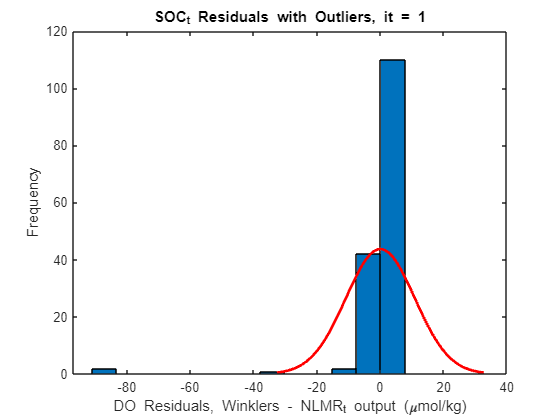

figure
histfit(mdl_dt1.Residuals.Raw)
title('SOC_d_t Residuals with Outliers, it = 1')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR_d_t output (\mumol/kg)')

% Find outliers based on median filter for it = 2 
Winkler_outliers1_dt = find(isoutlier(mdl_dt1.Residuals.Raw,'median') == 1);
mdl_dt2 = fitnlm(X_dt,Winklers_to_use,modelfun_dt,beta0_dt,'Exclude',Winkler_outliers1_dt)

mdl_dt2 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46268    0.00037574    1231.4    6.6797e-297
    b2      0.037928    9.3366e-05    406.23    3.9619e-226
    b3    0.00026081    4.7822e-05    5.4537     2.0388e-07


Number of observations: 150, Error degrees of freedom: 147
Root Mean Squared Error: 1.13
R-Squared: 0.991,  Adjusted R-Squared 0.991
F-statistic vs. zero model: 3.31e+06, p-value = 0

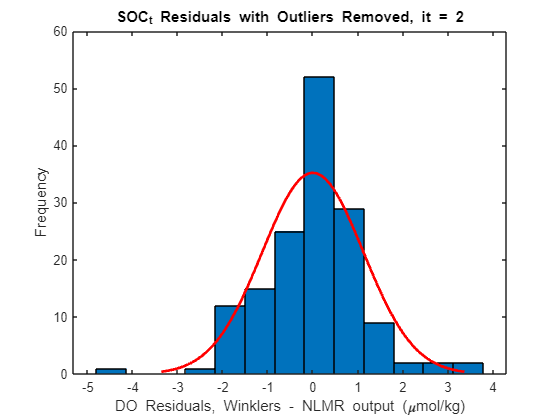

figure
histfit(mdl_dt2.Residuals.Raw)
title('SOC_d_t Residuals with Outliers Removed, it = 2')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 3 
ind = find(isoutlier(mdl_dt2.Residuals.raw,'median') == 1);
Winkler_outliers2_dt = [ind; Winkler_outliers1_dt];
% Exclude outliers from NLMR model 
mdl_dt3 = fitnlm(X_dt,Winklers_to_use,modelfun_dt,beta0_dt,'Exclude',Winkler_outliers2_dt)

mdl_dt3 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46247    0.00031714    1458.2    2.3588e-298
    b2      0.037986    7.8342e-05    484.87    1.8217e-230
    b3    0.00026271    4.0133e-05     6.546     1.0027e-09


Number of observations: 145, Error degrees of freedom: 142
Root Mean Squared Error: 0.937
R-Squared: 0.994,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.65e+06, p-value = 0

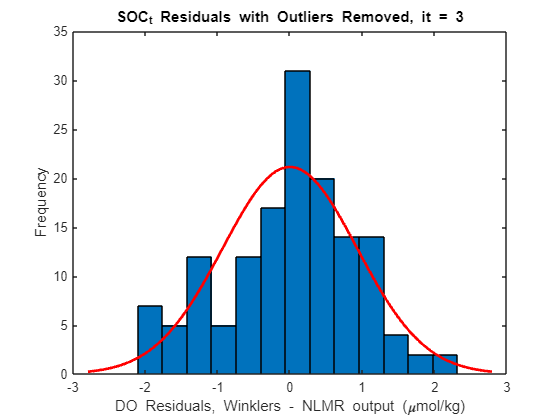

figure
histfit(mdl_dt3.Residuals.Raw)
title('SOC_d_t Residuals with Outliers Removed, it = 3')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 4 
ind = find(isoutlier(mdl_dt3.Residuals.raw,'median') == 1);
Winkler_outliers3_dt = [ind; Winkler_outliers2_dt];
% Exclude outliers from NLMR model 
mdl_dt4 = fitnlm(X_dt,Winklers_to_use,modelfun_dt,beta0_dt,'Exclude',Winkler_outliers3_dt)

mdl_dt4 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46247    0.00031714    1458.2    2.3588e-298
    b2      0.037986    7.8342e-05    484.87    1.8217e-230
    b3    0.00026271    4.0133e-05     6.546     1.0027e-09


Number of observations: 145, Error degrees of freedom: 142
Root Mean Squared Error: 0.937
R-Squared: 0.994,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.65e+06, p-value = 0

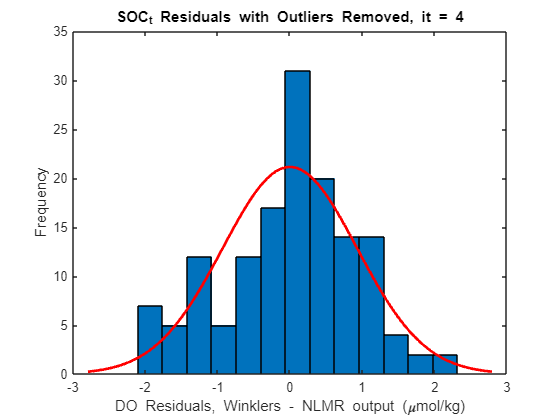

figure
histfit(mdl_dt4.Residuals.Raw)
title('SOC_d_t Residuals with Outliers Removed, it = 4')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 5 
ind = find(isoutlier(mdl_dt4.Residuals.raw,'median') == 1);
Winkler_outliers4_dt = [ind; Winkler_outliers3_dt];
% Exclude outliers from NLMR model 
mdl_dt5 = fitnlm(X_dt,Winklers_to_use,modelfun_dt,beta0_dt,'Exclude',Winkler_outliers4_dt)

mdl_dt5 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46247    0.00031714    1458.2    2.3588e-298
    b2      0.037986    7.8342e-05    484.87    1.8217e-230
    b3    0.00026271    4.0133e-05     6.546     1.0027e-09


Number of observations: 145, Error degrees of freedom: 142
Root Mean Squared Error: 0.937
R-Squared: 0.994,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.65e+06, p-value = 0

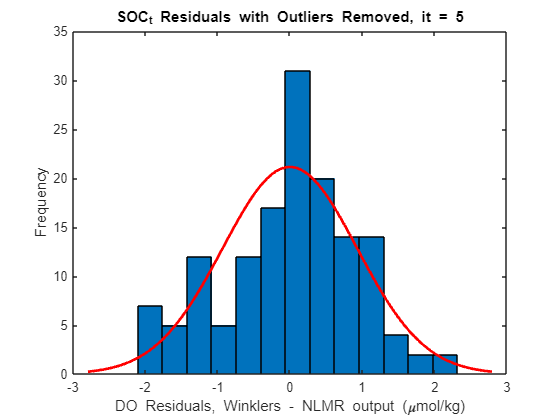

figure
histfit(mdl_dt5.Residuals.Raw)
title('SOC_d_t Residuals with Outliers Removed, it = 5')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% No more iteriations needed to determine outliers 

### Residuals for NMLR with SOC term that varies with cruise time

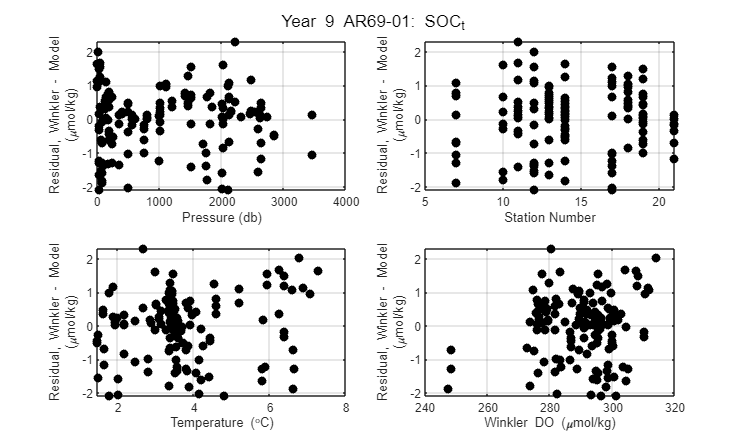

mdlcal_dt = mdl_dt5;
% cal for SOC_dt 
cal.SOCcalc_dt = mdlcal_dt.Coefficients.Estimate(1);
cal.Ecalc_dt = mdlcal_dt.Coefficients.Estimate(2);
cal.SOCrate_dt = mdlcal_dt.Coefficients.Estimate(3);
cal.Winkler1_outliers_dt = Winkler_outliers4_dt(Winkler_outliers4_dt < height(btlsum_tbl));
cal.Winkler2_outliers_dt = Winkler_outliers4_dt(Winkler_outliers4_dt > ...
    height(btlsum_tbl) & Winkler_outliers4_dt < 2*height(btlsum_tbl)) - height(btlsum_tbl);
cal.Winkler3_outliers_dt = Winkler_outliers4_dt(Winkler_outliers4_dt > ...
    2*height(btlsum_tbl) & Winkler_outliers4_dt < 3*height(btlsum_tbl)) - 2*height(btlsum_tbl);

out_NLMR_dt = sortrows([bad_casts(Winkler_outliers4_dt) btl_check(Winkler_outliers4_dt) ...
    Winklers_to_use(Winkler_outliers4_dt)/44.661/1000.*pdens(Winkler_outliers4_dt)],[1 2]);

f = figure;
f.Position = [100 100 840 500];
%Plot residuals versus pressure 
subplot(2,2,1)
plot(btlsum_tbl.prs, mdlcal_dt.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20);
hold on;
plot(btlsum_tbl.prs, mdlcal_dt.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.prs, mdlcal_dt.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Pressure (db)')
grid on

%Plot residuals versus cast number/time 
subplot(2,2,2)
plot(btlsum_tbl.Cast, mdlcal_dt.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20);
hold on;
plot(btlsum_tbl.Cast, mdlcal_dt.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.Cast, mdlcal_dt.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Station Number')
grid on

%Plot residuals versus temperature 
subplot(2,2,3)
plot(btlsum_tbl.t, mdlcal_dt.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20);
hold on;
plot(btlsum_tbl.t, mdlcal_dt.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.t, mdlcal_dt.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Temperature (\circC)')
grid on

%Plot residuals versus oxygen concentration 
subplot(2,2,4)
plot(btlsum_tbl.Winkler1_umolkg, mdlcal_dt.Residuals.raw(1:height(btlsum_tbl)),...
    '.k','Markersize',20); hold on;
plot(btlsum_tbl.Winkler2_umolkg, mdlcal_dt.Residuals.raw(height(btlsum_tbl)...
    +1:(height(btlsum_tbl)*2)),'.k','Markersize',20)
plot(btlsum_tbl.Winkler3_umolkg, mdlcal_dt.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Winkler DO (\mumol/kg)')
grid on
sgtitle('Year 9 AR69-01: SOC_d_t')

## Calculate SOC that varies by cast number 

X_cn = [[btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts; btlsum_tbl.oxy_volts],...
    [btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg; btlsum_tbl.O2sol_umolkg],...
    [btlsum_tbl.t; btlsum_tbl.t; btlsum_tbl.t],...
    [btlsum_tbl.prs; btlsum_tbl.prs; btlsum_tbl.prs],...
    [btlsum_tbl.Cast; btlsum_tbl.Cast; btlsum_tbl.Cast]];

% SBE functional form with SOC as a function of cast number 
modelfun_cn = @(b,x)((b(3)*x(:,5) + b(1)).*(x(:,1) + cal.VOFFSET)).*x(:,2)...
    .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
    .*exp((b(2)*x(:,4))./(x(:,3) + 273.15));

beta0_cn = [cal.SOC 0 0]; % Starting values for coefficient iterations 

mdl_cn1 = fitnlm(X_cn,Winklers_to_use,modelfun_cn,beta0_cn)

mdl_cn1 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
          Estimate         SE        tStat       pValue  
          _________    __________    ______    __________

    b1      0.44486     0.0056075    79.333    8.458e-127
    b2     0.039031    0.00087107    44.808    3.0395e-90
    b3    0.0010282    0.00036099    2.8483     0.0049962


Number of observations: 157, Error degrees of freedom: 154
Root Mean Squared Error: 10.9
R-Squared: 0.539,  Adjusted R-Squared 0.533
F-statistic vs. zero model: 3.68e+04, p-value = 1.29e-219

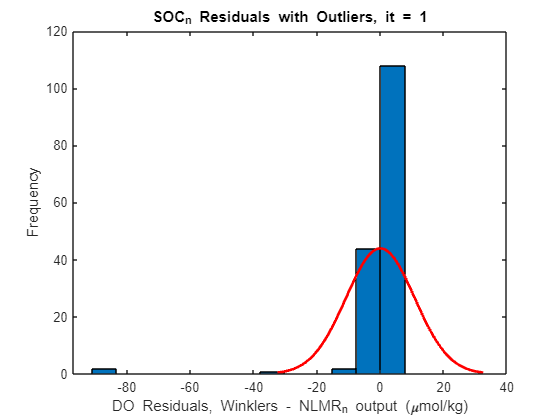

figure
histfit(mdl_cn1.Residuals.Raw)
title('SOC_c_n Residuals with Outliers, it = 1')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR_c_n output (\mumol/kg)')

% Find outliers based on median filter for it = 2 
Winkler_outliers1_cn = find(isoutlier(mdl_cn1.Residuals.Raw,'median') == 1);
mdl_cn2 = fitnlm(X_cn,Winklers_to_use,modelfun_cn,beta0_cn,'Exclude',Winkler_outliers1_cn)

mdl_cn2 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1        0.4608    0.00067165    686.08    1.2222e-262
    b2      0.037819    0.00010031    377.02    6.3764e-224
    b3    0.00024948    4.2513e-05    5.8684     2.7453e-08


Number of observations: 152, Error degrees of freedom: 149
Root Mean Squared Error: 1.25
R-Squared: 0.989,  Adjusted R-Squared 0.989
F-statistic vs. zero model: 2.75e+06, p-value = 0

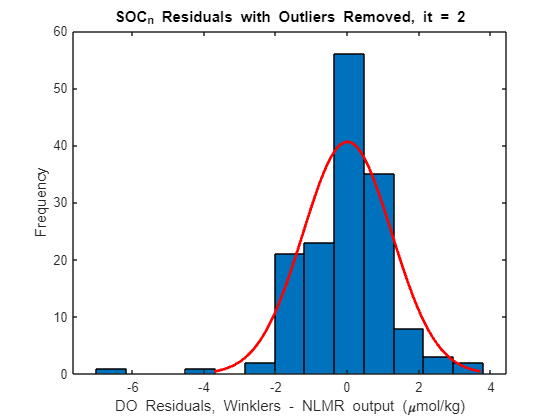

figure
histfit(mdl_cn2.Residuals.Raw)
title('SOC_c_n Residuals with Outliers Removed, it = 2')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 3 
ind = find(isoutlier(mdl_cn2.Residuals.raw,'median') == 1);
Winkler_outliers2_cn = [ind; Winkler_outliers1_cn];
% Exclude outliers from NLMR model 
mdl_cn3 = fitnlm(X_cn,Winklers_to_use,modelfun_cn,beta0_cn,'Exclude',Winkler_outliers2_cn)

mdl_cn3 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46109    0.00053619    859.95    1.0353e-270
    b2      0.037933    8.0603e-05    470.61    9.1882e-233
    b3    0.00021779     3.405e-05    6.3961     2.0606e-09


Number of observations: 148, Error degrees of freedom: 145
Root Mean Squared Error: 0.984
R-Squared: 0.993,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.32e+06, p-value = 0

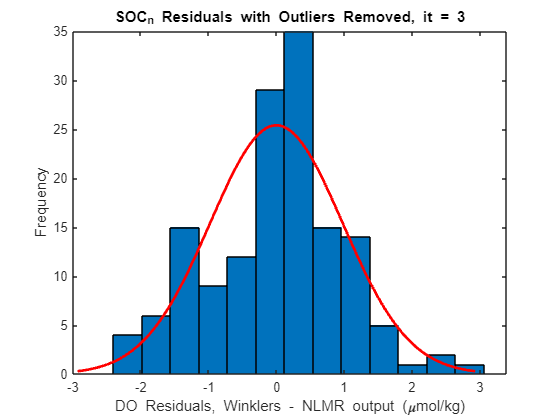

figure
histfit(mdl_cn3.Residuals.Raw)
title('SOC_c_n Residuals with Outliers Removed, it = 3')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 4 
ind = find(isoutlier(mdl_cn3.Residuals.raw,'median') == 1);
Winkler_outliers3_cn = [ind; Winkler_outliers2_cn];
% Exclude outliers from NLMR model 
mdl_cn4 = fitnlm(X_cn,Winklers_to_use,modelfun_cn,beta0_cn,'Exclude',Winkler_outliers3_cn)

mdl_cn4 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46092    0.00052343    880.57    1.4862e-270
    b2      0.037957    7.8642e-05    482.66    5.7684e-233
    b3    0.00022428    3.3118e-05    6.7719     2.9966e-10


Number of observations: 147, Error degrees of freedom: 144
Root Mean Squared Error: 0.955
R-Squared: 0.993,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.54e+06, p-value = 0

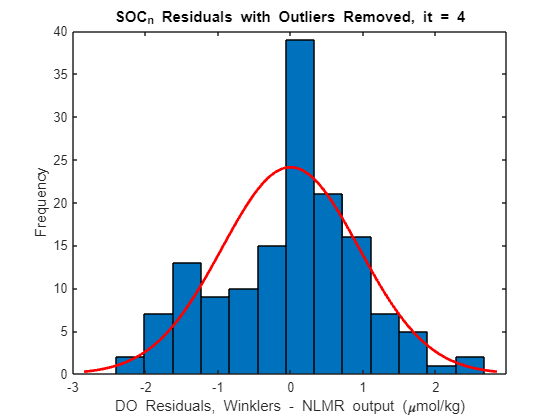

figure
histfit(mdl_cn4.Residuals.Raw)
title('SOC_c_n Residuals with Outliers Removed, it = 4')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% Find outliers based on median filter for it = 5 
ind = find(isoutlier(mdl_cn4.Residuals.raw,'median') == 1);
Winkler_outliers4_cn = [ind; Winkler_outliers3_cn];
% Exclude outliers from NLMR model 
mdl_cn5 = fitnlm(X_cn,Winklers_to_use,modelfun_cn,beta0_cn,'Exclude',Winkler_outliers4_cn)

mdl_cn5 = Nonlinear regression model:
    y ~ ((b3*x5 + b1)*(x1 + cal.VOFFSET))*x2*(1 + cal.A*x3 + cal.B*x3^2 + cal.C*x3^3)*exp((b2*x4)/(x3 + 273.15))

Estimated Coefficients:
           Estimate         SE        tStat       pValue   
          __________    __________    ______    ___________

    b1       0.46092    0.00052343    880.57    1.4862e-270
    b2      0.037957    7.8642e-05    482.66    5.7684e-233
    b3    0.00022428    3.3118e-05    6.7719     2.9966e-10


Number of observations: 147, Error degrees of freedom: 144
Root Mean Squared Error: 0.955
R-Squared: 0.993,  Adjusted R-Squared 0.993
F-statistic vs. zero model: 4.54e+06, p-value = 0

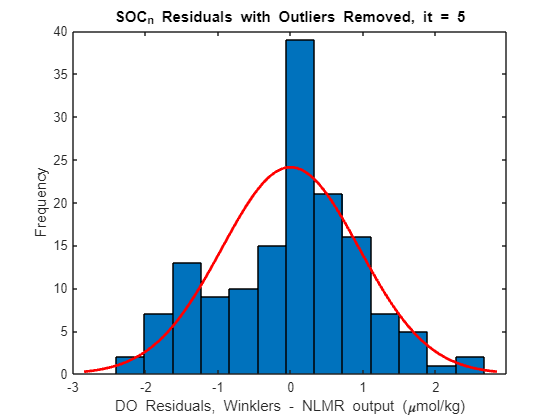

figure
histfit(mdl_cn5.Residuals.Raw)
title('SOC_c_n Residuals with Outliers Removed, it = 5')
ylabel('Frequency')
xlabel('DO Residuals, Winklers - NLMR output (\mumol/kg)')

% No more iteriations needed to determine outliers 

### Residuals for NMLR with SOC term that varies with cast number

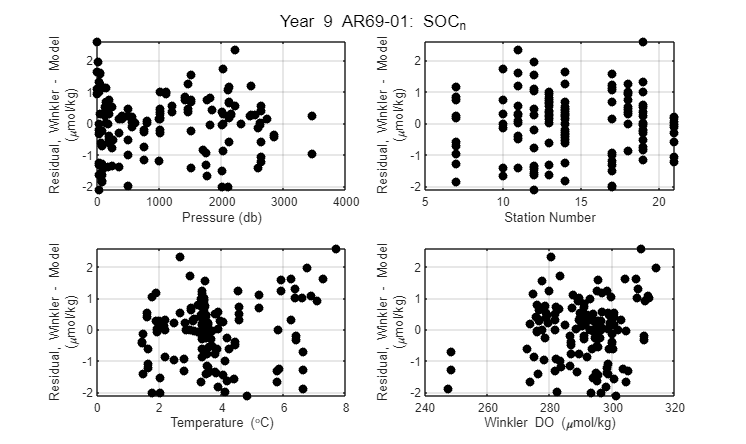

mdlcal_cn = mdl_cn5;
% cal.Winkler_outliers_cn = Winkler_outliers4_cn;
cal.SOCcalc_cn = mdlcal_cn.Coefficients.Estimate(1);
cal.Ecalc_cn = mdlcal_cn.Coefficients.Estimate(2);
cal.SOCrate_cn = mdlcal_cn.Coefficients.Estimate(3);
cal.Winkler1_outliers_cn = Winkler_outliers4_cn(Winkler_outliers4_cn < height(btlsum_tbl));
cal.Winkler2_outliers_cn = Winkler_outliers4_cn(Winkler_outliers4_cn > ...
    height(btlsum_tbl) & Winkler_outliers4_cn < 2*height(btlsum_tbl)) - height(btlsum_tbl);
cal.Winkler3_outliers_cn = Winkler_outliers4_cn(Winkler_outliers4_cn > ...
    2*height(btlsum_tbl) & Winkler_outliers4_cn < 3*height(btlsum_tbl)) - 2*height(btlsum_tbl);

out_NLMR_cn = sortrows([bad_casts(Winkler_outliers4_cn) btl_check(Winkler_outliers4_cn) ...
    Winklers_to_use(Winkler_outliers4_cn)/44.661/1000.*pdens(Winkler_outliers4_cn)],[1 2]);

f = figure;
f.Position = [100 100 840 500];
%Plot residuals versus pressure 
subplot(2,2,1)
plot(btlsum_tbl.prs, mdlcal_cn.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20); 
hold on;
plot(btlsum_tbl.prs, mdlcal_cn.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.prs, mdlcal_cn.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Pressure (db)')
grid on

%Plot residuals versus cast number/time 
subplot(2,2,2)
plot(btlsum_tbl.Cast, mdlcal_cn.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20); 
hold on;
plot(btlsum_tbl.Cast, mdlcal_cn.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.Cast, mdlcal_cn.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Station Number')
grid on

%Plot residuals versus temperature 
subplot(2,2,3)
plot(btlsum_tbl.t, mdlcal_cn.Residuals.raw(1:height(btlsum_tbl)), '.k','Markersize',20);
hold on;
plot(btlsum_tbl.t, mdlcal_cn.Residuals.raw(height(btlsum_tbl)+1:(height(btlsum_tbl)*2)),...
    '.k','Markersize',20)
plot(btlsum_tbl.t, mdlcal_cn.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Temperature (\circC)')
grid on

%Plot residuals versus oxygen concentration 
subplot(2,2,4)
plot(btlsum_tbl.Winkler1_umolkg, mdlcal_cn.Residuals.raw(1:height(btlsum_tbl)),...
    '.k','Markersize',20); hold on;
plot(btlsum_tbl.Winkler2_umolkg, mdlcal_cn.Residuals.raw(height(btlsum_tbl)...
    +1:(height(btlsum_tbl)*2)),'.k','Markersize',20)
plot(btlsum_tbl.Winkler3_umolkg, mdlcal_cn.Residuals.raw((height(btlsum_tbl)*2+1):end),...
    '.k','Markersize',20)
ylabel({'Residual, Winkler - Model','(\mumol/kg)'})
xlabel('Winkler DO (\mumol/kg)')
grid on
sgtitle('Year 9 AR69-01: SOC_c_n')

## Calibrates CTD oxygen values for bottle files 

- Using the function `calibrate_CTD_oxygen, `the user decides to apply no additional calibration (SOC_type = 0), a constant calibration (SOC_type = 1), or a calibration that depends on cruise time (SOC_type = 2) or cast number (SOC_type = 3).

- No additional calibration will calculate oxygen values (umol/kg) using the Seabird factory calibration coefficients. 

- I decided on a oxygen calibration that was dependent on cruise time (SOC_type =2) 

SOC_type = 2;
btlsum_tbl = calibrate_CTD_oxygen(btlsum_tbl,cal,SOC_type);

% Determine SOCdt term at start and end of the cruise 
dt = driftdt-driftdt(1);
SOCdtstart = dt(1)*cal.SOCrate_dt + cal.SOCcalc_dt;
SOCdtend = dt(end)*cal.SOCrate_dt + cal.SOCcalc_dt;

% Calculate the absolute residual mean once calibration has been applied 
Wink1 = btlsum_tbl.Winkler1_umolkg(btlsum_tbl.NLMR_Outlier1 == 0) ...
    - btlsum_tbl.DOcorr_umolkg(btlsum_tbl.NLMR_Outlier1 == 0);
Wink2 = btlsum_tbl.Winkler2_umolkg(btlsum_tbl.NLMR_Outlier2 == 0) ...
    - btlsum_tbl.DOcorr_umolkg(btlsum_tbl.NLMR_Outlier2 == 0);
Wink3 = btlsum_tbl.Winkler3_umolkg(btlsum_tbl.NLMR_Outlier3 == 0) ...
    - btlsum_tbl.DOcorr_umolkg(btlsum_tbl.NLMR_Outlier3 == 0);
Wink = [abs(Wink1); abs(Wink2); abs(Wink3)];  
absoulute_residual_mean = mean(Wink,'omitnan');
absolute_residual_std = std(Wink,'omitnan');

% Saves btlsum outputs with calibrated oxygen values 
btlsum = []; % Indexes by cast number leah_btl{5} == cast 5; 
% Combine files and calculate sea water properties for CTD sensor number 
for i = 1:height(salbtlcasts) % Number of bottle summary files 
    btlsum{salbtlcasts(i)} = btlsum_tbl(btlsum_tbl.Cast == salbtlcasts(i),:);
end

## Read in processed cast files 

### Read in SBE processed but uncalibrated DO cast files  

% Directories where files are stored, specific to KEF computer  
% Start/End of cast numbers in file string 
ns = 10; % Start of cast numbers in file name
ne = 12; % End of cast numbers in file name 

dc_dir = 'C:\Users\fogaren\Documents\SBE\Year9\downcasts'; % Only downcast files
uc_dir = 'C:\Users\fogaren\Documents\SBE\Year9\upcasts'; % Only upcast files
sal_dir = 'G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9\From_Leah';

%% Read in processed DO casts with uncalibrated oxygen voltages  

% Downcasts 
cd(dc_dir)
files = ls('*.cnv');
cast_num = str2num(files(:,ns:ne)); % Pulls out cast numbers 

DOdowncast = []; % Read all DO processed SBE cast into matlab 
for i = 1:length(cast_num)
    dcnv_in = readSBScnv(files(i,:));
    DOdowncast{cast_num(i)} = DO_cast(dcnv_in); 
end

% Upcasts 
cd(uc_dir)
files = ls('*.cnv');

DOupcast = []; % Read all DO processed SBE cast into matlab 
for i = 1:length(cast_num)
    ucnv_in = readSBScnv(files(i,:));
    DOupcast{cast_num(i)} = DO_cast(ucnv_in);
end

### Read in SBE processed salinity calibrated cast files  

%% Make sure salinity-calibrated cast numbers match uncalibrated DO cast numbers

cd(sal_dir)

% Start/End of cast numbers in file string 
ns = 10; % Start of cast numbers in file name
ne = 12; % End of cast numbers in file name 

downfiles = ls('*.dcc'); % List of calibrated cast files 
downcasts = str2num(downfiles(:,ns:ne)); % Pulls out cast numbers  

upfiles = ls('*.ucc');
upcasts = str2num(upfiles(:,ns:ne));

if cast_num == downcasts 
    clear downcasts % To use variable namelater 
else
    disp('Caution: Issue with Matching Downcast Numbers!')
end

if cast_num == upcasts
    clear upcasts % To use variable name later 
else 
    disp('Caution: Issue with Matching Upcast Numbers!')
end

dcc = []; % Read sal calibrated SBE casts into matlab 
for i = 1:length(cast_num)
    dcc_in =import_dcc(downfiles(i,:));
    dcc{cast_num(i)} = sal_cast(dcc_in);
end

ucc = [];
for i = 1:length(cast_num)
    ucc_in = import_dcc(upfiles(i,:));
    ucc{cast_num(i)} = sal_cast(ucc_in);
end

## Combine cast files and apply DO calibration 

% Sensor package to use when applying DO calibration  
CTD_sen = btlsum_tbl.CTD_sen(1); % same as bottle processing 
SOC_type = btlsum_tbl.SOC_type(1); 

CruiseStartTime = DOdowncast{cast_num(1)}.StartTimeUTC(1); % Needed for SOCdt 

btlsum = [];  
downcasts = []; upcasts = []; 
for i = 1:length(cast_num)
    btlsum{cast_num(i)} = btlsum_tbl(btlsum_tbl.Cast == cast_num(i),:); 
    downcasts{cast_num(i)} = process_cast(dcc{cast_num(i)}, DOdowncast{cast_num(i)},...
        CTD_sen, cal, SOC_type, CruiseStartTime);
    upcasts{cast_num(i)} = process_cast(ucc{cast_num(i)}, DOupcast{cast_num(i)},...
        CTD_sen, cal, SOC_type, CruiseStartTime);
end

## Figures showing calibrated DO casts with Winklers 

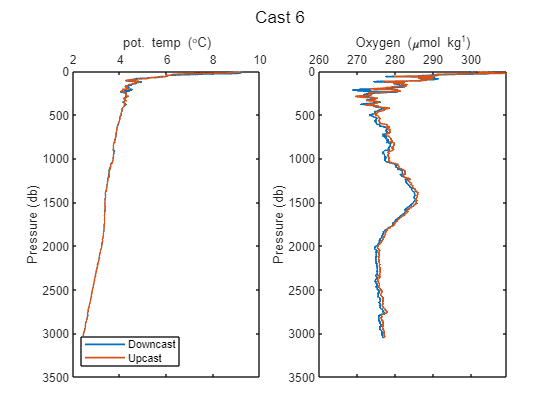

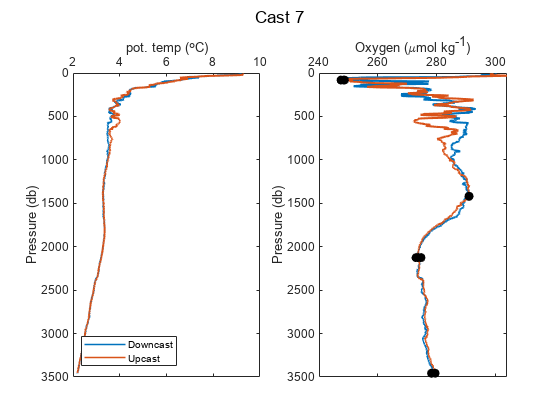

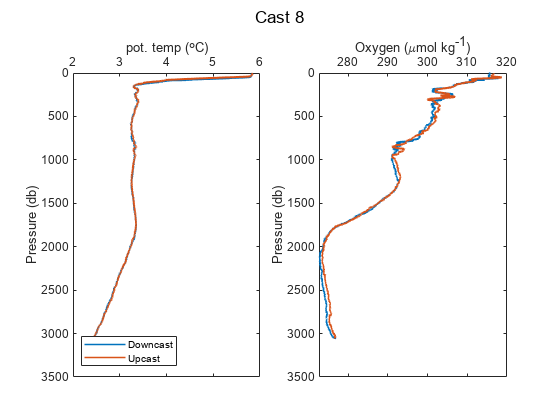

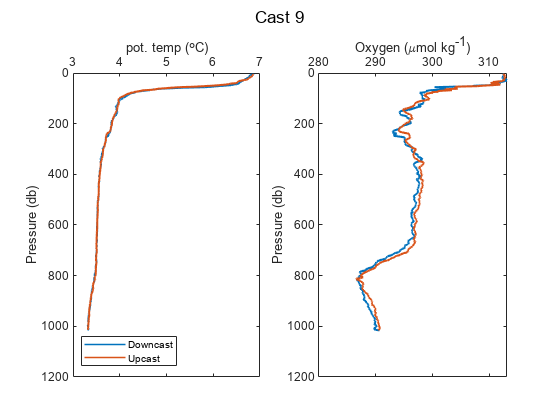

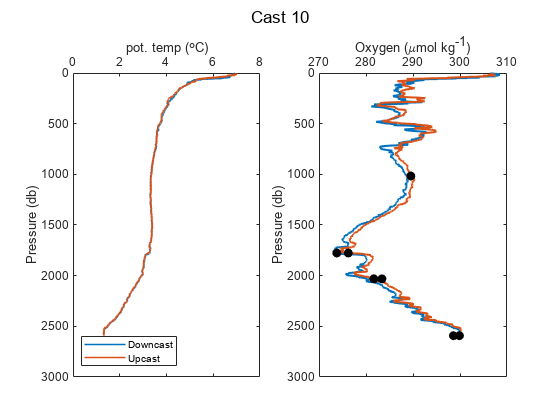

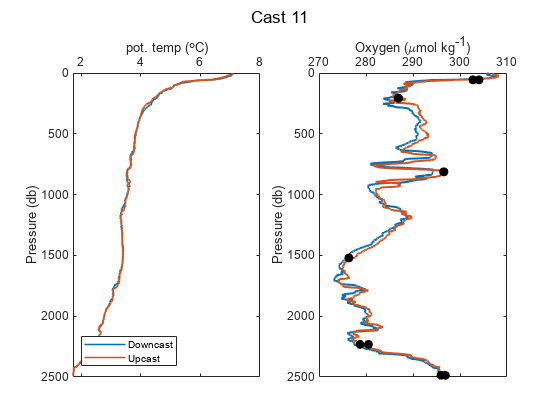

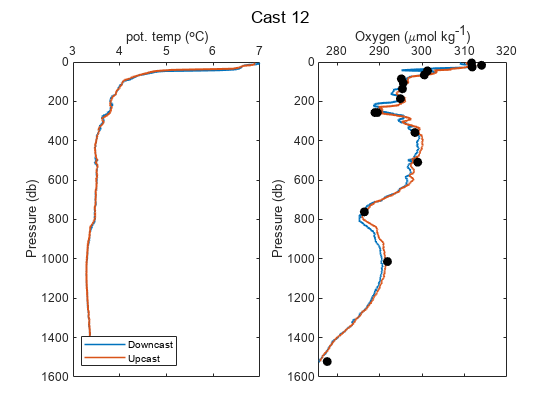

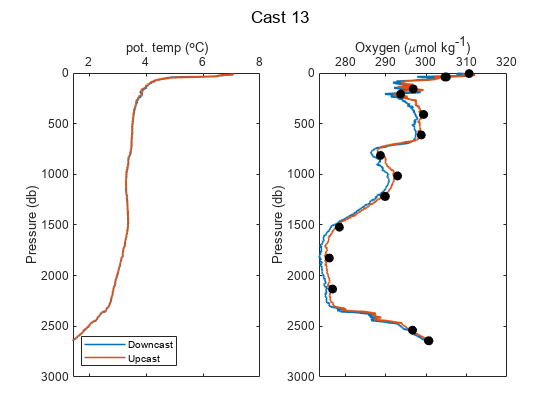

%% If want to look at Calibrated DO with Winklers by Cast  
for i = 1:length(cast_num)
    plot_calibrated_DO(downcasts{cast_num(i)},upcasts{cast_num(i)},btlsum{cast_num(i)})
end

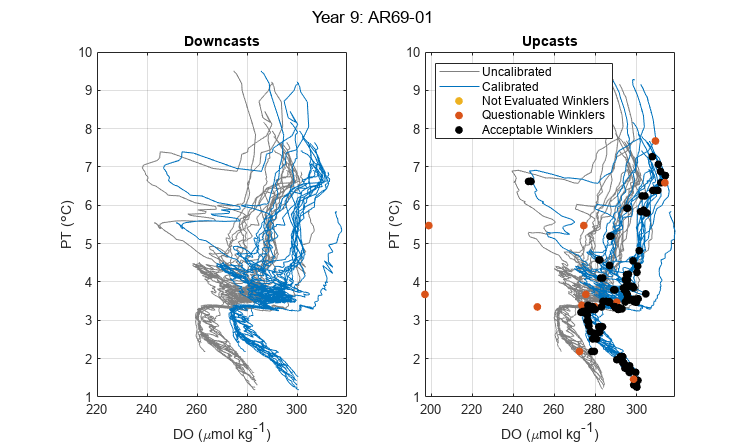

% Figure Grouped by downcasts/upcasts with Winklers
plot_calibrated_pTemp(downcasts,upcasts,cast_num,btlsum_tbl,cal,'Year 9: AR69-01')

## ====================FUNCTIONS=====================

## Combines bottle files and calculates additional GSW variables 

function btlsum = combine_btl_files(sal_btl_file,DO_btl_file,Winkler_table,CTD_sen)
    btlsum = Winkler_table; % Winklers for just the cast; change for different file formats  
    btlsum.Properties.VariableNames = {'Cruise','Asset','Cast','Bottle','Winkler1_mLL',...
        'Winkler2_mLL','Winkler3_mLL','Discrete_Salinity_psu'};

    % Format structure for conversion to table and convert to table; 
    % change for different Sal Bottle formatting  
    sal_btl = readtable(sal_btl_file,'FileType','text');
    sal_btl.Properties.VariableNames = {'Bottle','prs','temp1','temp2','th168','th268',...
        'sal1','sal2','CTDoxy_mLL_nohyst','flur_mgm3','tran','Meas_SAL','QUAL'};
    sal_btl.Meas_SAL(sal_btl.Meas_SAL == -9) = NaN; % replaces no data flag with NaN
    
    % Format structure for conversion to table and convert to table 
    btl = readtable(DO_btl_file,'TextType','string');
    % depends on which variables output from SBE processing software 
    vars = {'Bottle','Date','PrDM','DepSM','Latitude','Longitude','Sbeox0V'}; 
    btl = btl(:,vars);
    btl.Properties.VariableNames = {'Bottle','Date','PrDM','depth','lat','lon','oxy_volts'};
    btl.CTDcal(:) = {'True'};
    btl.CTDcal = string(btl.CTDcal);
    
    % Combine tables by Bottle variable 
    btlsum0 = join(sal_btl,btl,'Keys','Bottle');
    btlsum = join(btlsum,btlsum0,'Keys','Bottle');
 
    % Decide if using primary or secondary CTD sensor for temp and sal
    if CTD_sen == 1 % primary sensor (use unless something wrong with data)
        btlsum.t = btlsum.temp1; 
        btlsum.SP = btlsum.sal1; 
     end
    
    if CTD_sen == 2 % secondary sensor (use if primary sensor bad)
        btlsum.t = btlsum.temp2; 
        btlsum.SP = btlsum.sal2; 
    end    

    btlsum.CTD_sen = ones(length(btlsum.prs),1)*CTD_sen; 
    btlsum.SA = gsw_SA_from_SP(btlsum.SP,btlsum.prs,btlsum.lon,btlsum.lat);
    btlsum.CT = gsw_CT_from_t(btlsum.SA,btlsum.t,btlsum.prs);
    btlsum.pt = gsw_pt_from_CT(btlsum.SA,btlsum.CT);
    btlsum.O2sol_umolkg = gsw_O2sol(btlsum.SA,btlsum.CT,btlsum.prs,btlsum.lon,btlsum.lat);
    btlsum.rho = gsw_rho_CT_exact(btlsum.SA,btlsum.CT,btlsum.prs); % in situ density
    btlsum.prho = gsw_rho_CT_exact(btlsum.SA,btlsum.CT,0); % potential density with ref == surf
    btlsum.sigma0 = gsw_sigma0_CT_exact(btlsum.SA,btlsum.CT); % btlsum.prho - 1000 = btlsum.sigma0
    btlsum.Winkler1_umolkg = btlsum.Winkler1_mLL*1000*44.661./btlsum.prho; % Winklers 1 
    btlsum.Winkler2_umolkg = btlsum.Winkler2_mLL*1000*44.661./btlsum.prho; % Winklers 2 
    btlsum.Winkler3_umolkg = btlsum.Winkler3_mLL*1000*44.661./btlsum.prho; % Winklers 3; 
    % uses potential density 
   
     % Reorder variables and remove unnecessary ones
    btlvars = {'Cruise','Date','Cast','Bottle','prs','depth','lat','lon','temp1','temp2',...
        'sal1','sal2','Discrete_Salinity_psu','CTDcal','CTD_sen','t','CT','pt','SP','SA',...
        'rho','prho','sigma0','oxy_volts','Winkler1_mLL','Winkler2_mLL','Winkler3_mLL',...
        'Winkler1_umolkg','Winkler2_umolkg','Winkler3_umolkg','O2sol_umolkg'};
    btlsum = btlsum(:,btlvars);
end

## Calibrates CTD oxygen values from bottle files 

function btlsum = calibrate_CTD_oxygen(btlsum,cal,SOC_type)

x = [btlsum.oxy_volts,btlsum.O2sol_umolkg,btlsum.t,btlsum.prs];

    if SOC_type == 0 % Seabird Factory calibration 
    
        % SBE functional form without SOC drift 
        btlsum.DOcorr_umolkg = cal.SOC*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.E*x(:,4))./(x(:,3) + 273.15));
        outliers = [];
    end

    if SOC_type == 1 % Constant SOC value
    
        % SBE functional form without SOC drift 
        btlsum.DOcorr_umolkg = cal.SOCcalc*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.Ecalc*x(:,4))./(x(:,3) + 273.15));
        outliers1 = cal.Winkler1_outliers;
        outliers2 = cal.Winkler2_outliers;
        outliers3 = cal.Winkler3_outliers;
    end

    if SOC_type == 2 % SOC varies with cruise time
        dtx = datenum(btlsum.Date) - datenum(btlsum.Date(1)); 
        x = [x, dtx];
        
        % SBE functional form with SOC as a function of cruise time
        btlsum.DOcorr_umolkg = ((cal.SOCrate_dt*x(:,5)) + cal.SOCcalc_dt*(x(:,1) ...
            + cal.VOFFSET)).*x(:,2)...
            .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
            .*exp((cal.Ecalc_dt*x(:,4))./(x(:,3) + 273.15));
        outliers1 = cal.Winkler1_outliers_dt;
        outliers2 = cal.Winkler2_outliers_dt;
        outliers3 = cal.Winkler3_outliers_dt;
    end

    if SOC_type == 3 % SOC varies with cast number 

        x = [x,btlsum.Cast];
        
        % SBE functional form with SOC as a function of cruise time
        btlsum.DOcorr_umolkg = ((cal.SOCrate_cn*x(:,5)) + cal.SOCcalc_cn*(x(:,1) ...
            + cal.VOFFSET)).*x(:,2)...
            .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
            .*exp((cal.Ecalc_cn*x(:,4))./(x(:,3) + 273.15));
        outliers1 = cal.Winkler1_outliers_cn;
        outliers2 = cal.Winkler2_outliers_cn;
        outliers3 = cal.Winkler3_outliers_cn;
    end

        btlsum.SOC_type = ones(length(btlsum.prs),1)*SOC_type; 

        btlsum.NLMR_Outlier1 = zeros(length(btlsum.prs),1);
        btlsum.NLMR_Outlier1(outliers1) = 1;
        
        btlsum.NLMR_Outlier2 = zeros(length(btlsum.prs),1);
        btlsum.NLMR_Outlier2(outliers2) = 1;
        
        btlsum.NLMR_Outlier3 = zeros(length(btlsum.prs),1);
        btlsum.NLMR_Outlier3(outliers3) = 1;

            % Reorder variables and remove unnecessary ones
        btlvars = {'Cruise','Date','Cast','Bottle','prs','depth','lat','lon','temp1','temp2',...
            'sal1','sal2','Discrete_Salinity_psu','CTDcal','CTD_sen','t','CT','pt','SP','SA',...
            'rho','prho','sigma0','oxy_volts','O2sol_umolkg','Winkler1_mLL','Winkler2_mLL',...
            'Winkler3_mLL','Winkler1_umolkg','Winkler2_umolkg','Winkler3_umolkg','SOC_type',...
            'NLMR_Outlier1','NLMR_Outlier2','NLMR_Outlier3','DOcorr_umolkg'};
        btlsum = btlsum(:,btlvars);
end

## **Read in uncalibrated DO casts processed using SBE processing software **

%% Reads in DO processed casts
% The variables change depending on what user has output using SBE
% processing software 
function cast = DO_cast(cast)
    cast0 = cast;
    fields = {'source','DataFileType','instrumentheaders','userheaders','vars','longname',...
        'units','span','mvars','mvars_format','scan','lat','lon','nbin','flag',...
        'SeasaveVersion','softwareheaders','t090C','t190C','c0mScm','c1mScm','v7'};
    cast = rmfield(cast,fields);
    cast = struct2table(cast);
    cast.Properties.VariableNames = {'CastTimeS','prs','depth','oxy_volts'};
    cast.oxy_volts(cast.oxy_volts == -9.9900e-29) = NaN; % replaces no data flag with NaN
    cast.StartTimeUTC = ones(length(cast.CastTimeS),1)...
        *datenum(cast0.instrumentheaders.SystemUTC); 
    cast.StartTimeUTC = datetime(cast.StartTimeUTC,'ConvertFrom','datenum');
    cast.CastTimeUTC = cast.StartTimeUTC + cast.CastTimeS/3600/24;
    cast.CTDcal(:) = {'True'};
    cast.CTDcal = string(cast.CTDcal);
end

## **Read  in calibrated DO casts processed using SBE processing software **

%% Read in salinity calibrated casts 
% File formats vary by salinity calibration group/individual  
function sal_cast = sal_cast(sal_cast)

    fields = {'woce','date','time','oxcr','ox','tran','flu','alt'};
    sal_cast = rmfield(sal_cast,fields);
    sal_cast.station = sal_cast.station.*ones(length(sal_cast.prs),1);
    sal_cast.lat = sal_cast.lat.*ones(length(sal_cast.prs),1);
    sal_cast.lon = sal_cast.lon.*ones(length(sal_cast.prs),1);
    sal_cast = struct2table(sal_cast);
    sal_cast.Properties.VariableNames = {'Station','lat','lon','prs','temp1','temp2',...
        'sal1','sal2'};    
end


## Combine cast files and performs oxygen calibration 

% Combines Files and calibrate oxygen data
% sal_cal_cast = casts with calibrated salinity data
% DO_casts = casts with DO voltage processed with default hysteresis
% correction 

function cast = process_cast(sal_cal_cast,DO_cast,CTD_sen,cal,SOC_type,CruiseStartTime)

    cast = innerjoin(DO_cast,sal_cal_cast); 

    % Decide if using primary or secondary CTD sensor for temp and sal
    if CTD_sen == 1 % primary sensor (use unless something wrong with data)
        cast.t = cast.temp1; 
        cast.SP = cast.sal1; 
     end
    
    if CTD_sen == 2 % secondary sensor (use if primary sensor bad)
        cast.t = cast.temp2; 
        cast.SP = cast.sal2; 
    end   

    % Calculate other parameters of interest for downcast 
    cast.SA = gsw_SA_from_SP(cast.SP,cast.prs,cast.lon,cast.lat);
    cast.CT = gsw_CT_from_t(cast.SA,cast.t,cast.prs);
    cast.pt = gsw_pt_from_CT(cast.SA,cast.CT);  
    cast.O2sol_umolkg = gsw_O2sol(cast.SA,cast.CT,cast.prs,cast.lon,cast.lat);
    cast.rho = gsw_rho_CT_exact(cast.SA,cast.CT,cast.prs); % in situ density
    cast.prho = gsw_rho_CT_exact(cast.SA,cast.CT,0); % potential density with ref == surf
    cast.sigma0 = gsw_sigma0_CT_exact(cast.SA,cast.CT); % cast.prho - 1000 = cast.sigma0 
    cast.CTD_sen = ones(length(cast.prs),1)*CTD_sen; 
    cast.cruise_d = datenum(cast.StartTimeUTC) - datenum(CruiseStartTime); % Cruise time (d) 
    
    if SOC_type == 0 % Seabird factory calibration
        
        x = [cast.oxy_volts,cast.O2sol_umolkg,cast.t,cast.prs];
    
        % SBE functional form without SOC drift 
        cast.DOcorr_umolkg = cal.SOC*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.E*x(:,4))./(x(:,3) + 273.15));
    end   

    if SOC_type == 1 % Constant SOC value

        x = [cast.oxy_volts,cast.O2sol_umolkg,cast.t,cast.prs];
    
        % SBE functional form without constant SOC
        cast.DOcorr_umolkg = cal.SOCcalc*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.Ecalc*x(:,4))./(x(:,3) + 273.15));
    end

    if SOC_type == 2 % SOC varies with cruise time

        x = [cast.oxy_volts,cast.O2sol_umolkg,cast.t,cast.prs,cast.cruise_d];
        
        % SBE functional form with SOC as a function of cruise time
        cast.DOcorr_umolkg = ((cal.SOCrate_dt*x(:,5))...
            + cal.SOCcalc_dt*(x(:,1) + cal.VOFFSET)).*x(:,2)...
            .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
            .*exp((cal.Ecalc_dt*x(:,4))./(x(:,3) + 273.15));
    end

    if SOC_type == 3 % SOC varies with cast number 

        x = [cast.oxy_volts,cast.O2sol_umolkg,cast.t,cast.prs,cast.Station];
        
        % SBE functional form with SOC as a function of cruise time
        cast.DOcorr_umolkg = ((cal.SOCrate_cn*x(:,5))...
            + cal.SOCcalc_cn*(x(:,1) + cal.VOFFSET)).*x(:,2)...
            .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
            .*exp((cal.Ecalc_cn*x(:,4))./(x(:,3) + 273.15));
    end

    cast.SOC_type = ones(length(cast.prs),1)*SOC_type; 

    % Reorder variables and remove unnecessary ones
    vars = {'Station','prs','depth','lat','lon','temp1','temp2','sal1','sal2',...
        'CastTimeS','CastTimeUTC','StartTimeUTC','cruise_d','CTDcal','CTD_sen',...
        't','CT','pt','SP','SA','rho','prho','sigma0','oxy_volts','DOcorr_umolkg',...
        'O2sol_umolkg','SOC_type'};
    cast = cast(:,vars); 
    
end

## Figures showing calibrated DO data 

function plot_calibrated_DO(downcasts,upcasts,btlsum)

    if height(btlsum) == 1 
         
        figure
        subplot(1,2,1)
        plot(downcasts.pt,downcasts.prs,'Linewidth',1.2)
        hold on
        plot(upcasts.pt,upcasts.prs,'Linewidth',1.2)
        axis ij
        ylabel('Pressure (db)')
        xlabel('pot. temp (\circC)')
        ax = gca;
        ax.XAxisLocation = 'top';
        legend('Downcast','Upcast','Location','SW')

        subplot(1,2,2)
        plot(downcasts.DOcorr_umolkg,downcasts.prs,'Linewidth',1.2)
        hold on
        plot(upcasts.DOcorr_umolkg,upcasts.prs,'Linewidth',1.2)
        axis ij
        ylabel('Pressure (db)')
        xlabel('Oxygen (\mumol kg^-^1)')
        ax = gca;
        ax.XAxisLocation = 'top';
        sgtitle(['Cast ' num2str(downcasts.Station(1))])
    end
    
            
    if height(btlsum) ~= 1 
        
        figure
        subplot(1,2,1)
        plot(downcasts.pt,downcasts.prs,'Linewidth',1.2)
        hold on
        plot(upcasts.pt,upcasts.prs,'Linewidth',1.2)
        axis ij
        ylabel('Pressure (db)')
        xlabel('pot. temp (\circC)')
        ax = gca;
        ax.XAxisLocation = 'top';
        legend('Downcast','Upcast','Location','SW')

        subplot(1,2,2)
        plot(downcasts.DOcorr_umolkg,downcasts.prs,'Linewidth',1.2)
        hold on
        plot(upcasts.DOcorr_umolkg,upcasts.prs,'Linewidth',1.2)
        plot(btlsum.Winkler1_umolkg(btlsum.NLMR_Outlier1 == 0),...
            btlsum.prs(btlsum.NLMR_Outlier1 == 0),'ok','MarkerFaceColor','k')
        plot(btlsum.Winkler2_umolkg(btlsum.NLMR_Outlier2 == 0),...
            btlsum.prs(btlsum.NLMR_Outlier2 == 0),'ok','MarkerFaceColor','k')
        plot(btlsum.Winkler3_umolkg(btlsum.NLMR_Outlier3 == 0),...
            btlsum.prs(btlsum.NLMR_Outlier3 == 0),'ok','MarkerFaceColor','k')
        axis ij
        ylabel('Pressure (db)')
        xlabel('Oxygen (\mumol kg^-^1)')
        ax = gca;
        ax.XAxisLocation = 'top';
        sgtitle(['Cast ' num2str(downcasts.Station(1))])
    end

end

function plot_calibrated_pTemp(downcasts,upcasts,cast_num,btlsum,cal,TitleString)
% For plotting purposes 
grey = [0.5     0.5     0.5];
blue = [0     0.44706     0.74118];
red = [0.85098     0.32549    0.098039];
yellow = [0.92941     0.69412     0.12549];

f = figure;
f.Position = [100 100 840 500];
subplot(1,2,1)
for i = 1:length(cast_num)

    x = [downcasts{cast_num(i)}.oxy_volts downcasts{cast_num(i)}.O2sol_umolkg ...
        downcasts{cast_num(i)}.t downcasts{cast_num(i)}.prs];
    DOuncorr_umolkg = cal.SOC*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.E*x(:,4))./(x(:,3) + 273.15));
    plot(DOuncorr_umolkg,downcasts{cast_num(i)}.pt,'Linewidth',1,'Color',grey)
    hold on
end

for i = 1:length(cast_num)    
    plot(downcasts{cast_num(i)}.DOcorr_umolkg,downcasts{cast_num(i)}.pt,...
        'Linewidth',1,'Color',blue)
end
ylabel('PT (\circC)')
xlabel('DO (\mumol kg^-^1)')
title('Downcasts')
grid on

subplot(1,2,2)
plot(NaN,NaN,'Color',grey) % For legend 
hold on
plot(NaN,NaN,'Color',blue)
plot(NaN,NaN,'.','Markersize',20,'Color',yellow)
plot(NaN,NaN,'.','markersize',20,'Color',red)
plot(NaN,NaN,'.k','markersize',20)

for i = 1:length(cast_num)

    x = [upcasts{cast_num(i)}.oxy_volts upcasts{cast_num(i)}.O2sol_umolkg ...
        upcasts{cast_num(i)}.t upcasts{cast_num(i)}.prs];
    DOuncorr_umolkg = cal.SOC*(x(:,1) + cal.VOFFSET).*x(:,2)...
        .*(1 + cal.A*x(:,3) + cal.B*x(:,3).^2 + cal.C*x(:,3).^3)...
        .*exp((cal.E*x(:,4))./(x(:,3) + 273.15));
    plot(DOuncorr_umolkg,upcasts{cast_num(i)}.pt,'Linewidth',1,'Color',grey)
end

for i = 1:length(cast_num)
    plot(upcasts{cast_num(i)}.DOcorr_umolkg,upcasts{cast_num(i)}.pt,...
        'Linewidth',1,'Color',blue)
end
plot(btlsum.Winkler1_umolkg(btlsum.NLMR_Outlier1==1),btlsum.pt(btlsum.NLMR_Outlier1==1),...
    '.','markersize',20,'Color',red)
plot(btlsum.Winkler1_umolkg(btlsum.NLMR_Outlier1==0),btlsum.pt(btlsum.NLMR_Outlier1==0),...
    '.k','markersize',20)
plot(btlsum.Winkler2_umolkg(btlsum.NLMR_Outlier2==1),btlsum.pt(btlsum.NLMR_Outlier2==1),...
    '.','markersize',20,'Color',red)
plot(btlsum.Winkler2_umolkg(btlsum.NLMR_Outlier2==0),btlsum.pt(btlsum.NLMR_Outlier2==0),...
    '.k','markersize',20)
plot(btlsum.Winkler3_umolkg(btlsum.NLMR_Outlier3==1),btlsum.pt(btlsum.NLMR_Outlier3==1),...
    '.','markersize',20,'Color',red)
plot(btlsum.Winkler3_umolkg(btlsum.NLMR_Outlier3==0),btlsum.pt(btlsum.NLMR_Outlier3==0),...
    '.k','markersize',20)
ylabel('PT (\circC)')
xlabel('DO (\mumol kg^-^1)')
title('Upcasts')
grid on
sgtitle(TitleString)
legend('Uncalibrated','Calibrated','Not Evaluated Winklers','Questionable Winklers',...
    'Acceptable Winklers','Location','NW')
end